# Part 3: Control

load('Exercise_2_Workspace.mat')

# Preprocessing

Linear model from Exercise 2 requires a small change, since we measure the derivative of Euler angles (from Gyro), not Eurel angles themselves. So the linear model needs to output the correct sensor data.

#### Linerizing the model

TakeStep = 0; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN

% for linearizing the model x0 was used instead of xss, because xss had some
% artefacts from numerical solving (meaning it was not purly equal to zero)
[AA,BB,CC,DD] = linmod('Exercise_3_Nonlinear_Euler',x0,uss);
sys = ss(AA,BB,CC,DD)

sys =
 
  A = 
           x1     x2     x3     x4     x5     x6     x7     x8     x9    x10    x11    x12
   x1       0      0      0      1      0      0      0      0      0      0      0      0
   x2       0      0      0      0      1      0      0      0      0      0      0      0
   x3       0      0      0      0      0      1      0      0      0      0      0      0
   x4       0      0      0  -0.01      0      0      0   9.81      0      0      0      0
   x5       0      0      0      0  -0.01      0  -9.81      0      0      0      0      0
   x6       0      0      0      0      0  -0.01      0      0      0      0      0      0
   x7       0      0      0      0      0      0      0      0      0      1      0      0
   x8       0      0      0      0      0      0      0      0      0      0      1      0
   x9       0      0      0      0      0      0      0      0      0      0      0      1
   x10      0      0      0      0      0      0      0      0      0      

#### Linear System Analysis

damp(AA)

                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
  0.00e+00    -1.00e+00       0.00e+00               Inf    
  0.00e+00    -1.00e+00       0.00e+00               Inf    
  0.00e+00    -1.00e+00       0.00e+00               Inf    
 -1.00e-02     1.00e+00       1.00e-02          1.00e+02    
 -1.00e-02     1.00e+00       1.00e-02          1.00e+02    
 -1.00e-02     1.00e+00       1.00e-02          1.00e+02    
  0.00e+00    -1.00e+00       0.00e+00               Inf    
  0.00e+00    -1.00e+00       0.00e+00               Inf    
  0.00e+00    -1.00e+00       0.00e+00               Inf    
  0.00e+00    -1.00e+00       0.00e+00               Inf    
  0.00e+00    -1.00e+00       0.00e+00               Inf    
  0.00e+00    -1.00e+00       0.00e+00               Inf    


rank(ctrb(AA,BB))

ans = 12

rank(obsv(AA,CC))

ans = 12

# Exercise 3.1 - Closing attitude loop

>>> Using the non-linear model of Exercise 2.1 (or 2.2), close a feedback control loop to control the attitude, to allow setting roll, pitch, yaw and altitude references. Choose the gains of the PID by tuning on the linearized system, by minimizing the settling time while ensuring

that the controlled system is critically damped (no overshoot), and plot the step response for a step of... Show your results and explain them.

#### Formulas

(For details see: [https://andrew.gibiansky.com/blog/physics/quadcopter-dynamics/](https://andrew.gibiansky.com/blog/physics/quadcopter-dynamics/) )

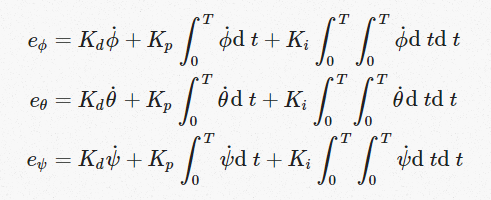

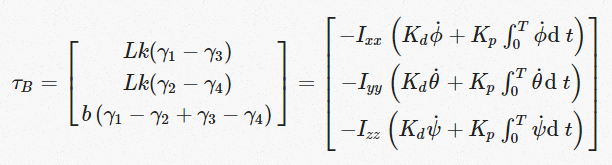

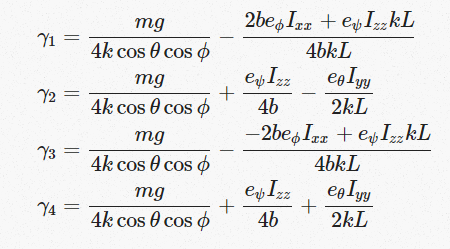

#### Gains

% ATTITUDE PID CONTROLER
att_Kp = 10;  % proportional gain
att_Ki = 0;  % integral gain
att_Kd = 10;  % derivative gain

% posZ PI CONTROLER
posZ_Kp = 5; % proportional gain
posZ_Ki = 0; % integral gain
posZ_Kd = 5; % derivative gain
posZ_N = 20;
% max values for a drone
maxRPM = 500;

#### Starting off with linear model

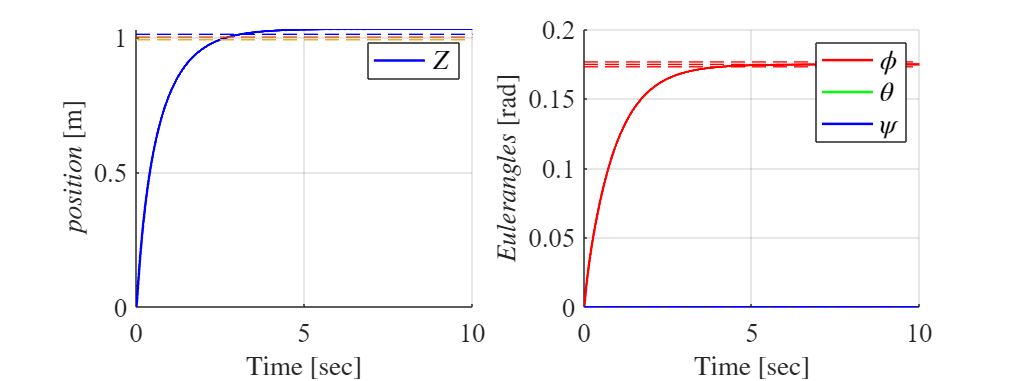

simTime = 10;
t = (0:.1:simTime)'; % Time vector
Attitude_Ref = [0.174533, 0, 0]';   % 10 deg = 0.174533 radians
%Gyro_Ref = [0, 0, 0]';
posZ_Ref = [1]';


uAttitude_Ref = Attitude_Ref*ones(1,length(t));
%uGyro_Ref = Gyro_Ref*ones(1,length(t));
uposZ_Ref = posZ_Ref*ones(1,length(t));

simOut = sim('Exercise_3_Linear_Euler_new', simTime, [], [t, uAttitude_Ref', uposZ_Ref']);
plotAttitudeRespone(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data, [Attitude_Ref', posZ_Ref'], 0.01) % you can find declaration of a function at the end of the file

% subplot(1,2,1)
% ylim([0.9 1.1])
% subplot(1,2,2)
% ylim([0.000 0.200])

#### Nonlinear model

% ATTITUDE PID CONTROLER
att_Kp = 10;  % proportional gain
att_Ki = 0;  % integral gain
att_Kd = 10;  % derivative gain

% posZ PI CONTROLER
posZ_Kp = 0.024731; % proportional gain
posZ_Ki = 0; % integral gain
posZ_Kd = 1.5462; % derivative gain
posZ_N = 17.7275;
% max values for a drone
maxRPM = 500;

TorV = 0;
simTime = 10;
t = (0:.1:simTime)'; % Time vector
Attitude_Ref = [0.174533, 0, 0]';   % 10 deg = 0.174533 radians
%Gyro_Ref = [0, 0, 0]';
posZ_Ref = [1]';


uAttitude_Ref = Attitude_Ref*ones(1,length(t));
%uGyro_Ref = Gyro_Ref*ones(1,length(t));
uposZ_Ref = posZ_Ref*ones(1,length(t));

simOut = sim('My_Nonlinear_with_controller_draft', simTime, [], [t, uAttitude_Ref', uposZ_Ref']);

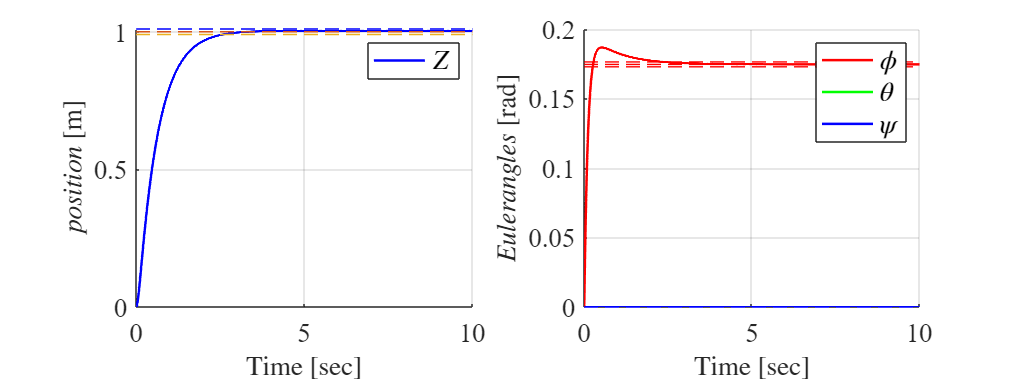

plotAttitudeRespone(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data, [Attitude_Ref', posZ_Ref'], 0.01)

TorV = 1; % 1: run my code 0 run V code

function plotAttitudeRespone(time, data, reference, error)
           
    angPhiRef   = reference(1)*ones(size(time));
    angPhiRefMin = angPhiRef * (1 - error);
    angPhiRefMax = angPhiRef * (1 + error);
    
    angThetaRef = reference(2)*ones(size(time));
    angThetaRefMin = angThetaRef * (1 - error);
    angThetaRefMax = angThetaRef * (1 + error);
    
    angPsiRef   = reference(3)*ones(size(time));
    angPsiRefMin = angPsiRef * (1 - error);
    angPsiRefMax = angPsiRef * (1 + error);
    
    posZRef     = reference(4)*ones(size(time));
    posZRefMin = posZRef * (1 - error);
    posZRefMax = posZRef * (1 + error);
    
    posX = data(1,:);
    posY = data(2,:);
    posZ = data(3,:);
    
    angPhi      = data(4,:);
    angTheta    = data(5,:);
    angPsi      = data(6,:);
    
    
    figure, h1 = subplot(1,2,1); set(h1,'FontName','times','FontSize',16)
    hold on, grid on
    % sim data
    plot(time, posZ,'b','LineWidth',1.5)
    % reference
    plot(time, posZRef, time, posZRefMin, time, posZRefMax,'b','LineWidth', 0.5, 'LineStyle','--')
    xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
    ylabel('$position$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
    legend('$Z$', 'FontName','times','FontSize',16,'Interpreter','latex')
    h2 = subplot(1,2,2); set(h2,'FontName','times','FontSize',16)
    hold on, grid on
    % sim data
    plot(time, angPhi,'r', time, angTheta,'g', time, angPsi,'b', 'LineWidth',1.5)
    % reference
    plot(time, angPhiRef, 'r', time, angPhiRefMin,'r', time, angPhiRefMax, 'r', 'LineWidth', 0.5, 'LineStyle','--')
    plot(time, angThetaRef, 'g', time, angThetaRefMin, 'g', time, angThetaRefMax, 'g', 'LineWidth', 0.5, 'LineStyle','--')
    plot(time, angPsiRef, 'b', time, angPsiRefMin, 'b', time, angPsiRefMax, 'b', 'LineWidth', 0.5, 'LineStyle','--')
    xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
    ylabel('$Euler angles$ [rad]','FontName','times','FontSize',16,'Interpreter','latex')
    legend('$\phi$', '$\theta$', '$\psi$', 'FontName','times','FontSize',16,'Interpreter','latex')
    set(gcf,'units','points','position',[0,0,800,300])
end

function plotSimOutput(time, data)
        
    posX = data(1,:);
    posY = data(2,:);
    posZ = data(3,:);
    
    angPhi      = data(4,:);
    angTheta    = data(5,:);
    angPsi      = data(6,:);
    
    
    figure, h1 = subplot(1,2,1); set(h1,'FontName','times','FontSize',16)
    hold on, grid on
    plot(time, posX,'r', time, posY,'g', time, posZ,'b','LineWidth',1.5)
    xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
    ylabel('$position$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
    legend('$X$', '$Y$', '$Z$', 'FontName','times','FontSize',16,'Interpreter','latex')
    h2 = subplot(1,2,2); set(h2,'FontName','times','FontSize',16)
    hold on, grid on
    plot(time, angPhi,'r', time, angTheta,'g', time, angPsi,'b', 'LineWidth',1.5)
    xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
    ylabel('$Euler angles$ [rad]','FontName','times','FontSize',16,'Interpreter','latex')
    legend('$\phi$', '$\theta$', '$\psi$', 'FontName','times','FontSize',16,'Interpreter','latex')
    set(gcf,'units','points','position',[0,0,600,300])
end